### Problem 2.

Solve the following problems by programming the steepest descent method and the conjugate gradient method.

- Rosenbrok's function (the minimum is in a parabolic valley): $f=100{\left(x_2 -x_1^2 \right)}^2 +{\left(1-x_1 \right)}^2$, where ${\mathit{\mathbf{x}}}_0 ={\left\lbrack \begin{array}{cc}
-1\ldotp 2 & 1
\end{array}\right\rbrack }^{\mathrm{T}}$

- Wood's function (this problem has several local minima): $f=100{\left(x_2 -x_1^2 \right)}^2 +5{\left(1-x_1 \right)}^2 +90{\left(x_4 -x_3^2 \right)}^2 +{\left(1-x_3 \right)}^2 +10\ldotp 1\left\lbrace {\left(x_2 -1\right)}^2 +{\left(x_4 -1\right)}^2 \right\rbrace +19\ldotp 8\left(x_2 -1\right)\left(x_4 -1\right)$, where $x_0 ={\left\lbrack \begin{array}{cccc}
-3 & -1 & -3 & -1
\end{array}\right\rbrack }^{\mathrm{T}}$

close all; clear all; clc;

**Rosenbrok's function**

fcnRosenbrok = @(x) (100*(x(2) - x(1)^2)^2 + (1 - x(1))^2);
x0Rosenbrok = [-1.2, 1]';

**Wood's function**

fcnWood = @(x) 100*(x(2) - x(1)^2)^2 + 5*(1 - x(1))^2 + 90*(x(4) - x(3)^2)^2 + (1 - x(3))^2 + 10.1*((x(2) - 1)^2 + (x(4) - 1)^2) + 19.8*(x(2) - 1)*(x(4) - 1);
x0Wood = [-3, -1, -3, -1]';

#### (a)

Plot the iteration history of your function and find the optimal points.

At initializing step, $g_0 =\nabla f\left(x_0 \right),d_0 =-g_0$.

gradRosenbrok = @(x) [-400*(x(2) - x(1)^2)*x(1) - 2*(1 - x(1));...
    200*(x(2) - x(1)^2)];

Using **Steepest Descent method** (1st order Gradient method)

xHistorySteepest =x0Rosenbrok;
xValuesSteepest = fcnRosenbrok(x0Rosenbrok);

% Initializing
x_prev = x0Rosenbrok;
max_iter = 10000;
iter = 1;
is_converged = false;
k = 0.001;

while iter < max_iter
    x_new = x_prev - k*gradRosenbrok(x_prev);
    xHistorySteepest = [xHistorySteepest, x_new];
    xValuesSteepest = [xValuesSteepest, fcnRosenbrok(x_new)];
    if (fcnRosenbrok(x_prev) < fcnRosenbrok(x_new))
        break;
    end
    x_prev = x_new;
    iter = iter + 1;
end

Using **Conjugate Gradient method**.

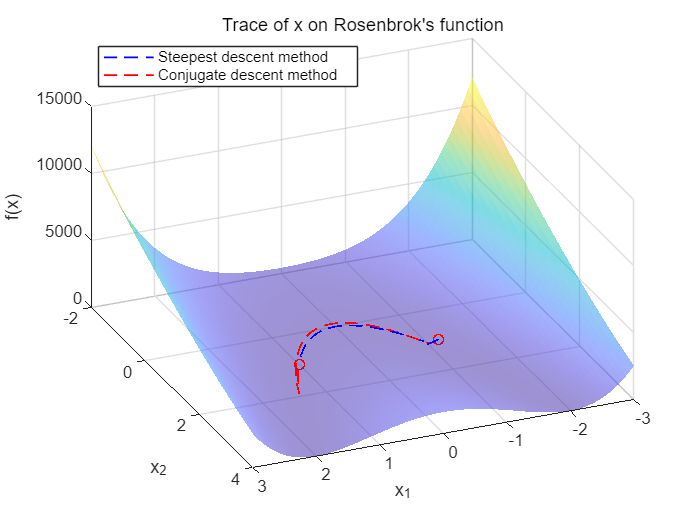

xHistoryConjugate =x0Rosenbrok;
xValuesConjugate = fcnRosenbrok(x0Rosenbrok);

% Initializing
max_iter = 100;
iter = 1;
is_converged = false;
is_first = true;
threshold = 1e-12;
margin = [0, 1]; % Bi-section searching margin
x_prev = x0Rosenbrok;

% Nemerical optimization loop
while and(iter < max_iter, ~is_converged)
    x_grad = gradRosenbrok(x_prev);
    if is_first
        is_first = false;
        dir_prev = -x_grad;
        alpha = bi_section_search(fcnRosenbrok, x_prev, dir_prev, margin);
    else
        beta = (x_grad'*x_grad)/(x_grad_prev'*x_grad_prev);
        dir = -x_grad + beta * dir_prev;
        alpha = bi_section_search(fcnRosenbrok, x_prev, dir, margin);
        dir_prev = dir;
    end
    x_new = x_prev + alpha*dir_prev;
    if abs(fcnRosenbrok(x_new) - fcnRosenbrok(x_prev)) < threshold
        is_converged = true;
    end
    if fcnRosenbrok(x_prev) < fcnRosenbrok(x_new)
        break;
    end
    x_prev = x_new;
    x_grad_prev = x_grad;
    xHistoryConjugate = [xHistoryConjugate, x_prev];
    xValuesConjugate = [xValuesConjugate, fcnRosenbrok(x_prev)];
    iter = iter + 1;
end
x1_range = linspace(-3, 3, 100);
x2_range = linspace(-2, 4, 100);
[X1, X2] = meshgrid(x1_range, x2_range);

Z = arrayfun(@(x1, x2) fcnRosenbrok([x1; x2]), X1, X2);

figRosenbrok = figure(1);
surf(X1, X2, Z, 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on; grid on;
steepestTraj = plot3(xHistorySteepest(1,:), xHistorySteepest(2,:), xValuesSteepest, 'b--', 'LineWidth', 1);
scatter3(xHistorySteepest(1,1), xHistorySteepest(2,1), xValuesSteepest(1), 'blue', 'LineWidth',1);
scatter3(xHistorySteepest(1,end), xHistorySteepest(2,end), xValuesSteepest(end), 'blue', 'LineWidth',1);
conjugateTraj = plot3(xHistoryConjugate(1,:), xHistoryConjugate(2,:), xValuesConjugate, 'r--', 'LineWidth', 1);
scatter3(xHistoryConjugate(1,1), xHistoryConjugate(2,1), xValuesConjugate(1), 'red', 'LineWidth',1);
scatter3(xHistoryConjugate(1,end), xHistoryConjugate(2,end), xValuesConjugate(end), 'red', 'LineWidth',1);
xlabel('x_1'); ylabel('x_2'); zlabel('f(x)'); title("Trace of x on Rosenbrok's function");
legend([steepestTraj, conjugateTraj], {"Steepest descent method", "Conjugate descent method"}, "Location", "best");
view([-203 41]);

Using the conjugate gradient method, $x$ converged to ${\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack }^{\mathrm{T}}$ at **68 iteration** and its function result is $9\ldotp 6051e-11$.

Both methods appear to converge to ${\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack }^{\mathrm{T}}$, but it can be seen that the **68th iteration of the conjugate gradient method is closer to the minimum than the 10000 iteration of the steep descent method.**

gradWood = @(x) [200*(x(2) - x(1)^2)*(-2*x(1)) - 10*(1 - x(1));...
    200*(x(2) - x(1)^2) + 20.2*(x(2) - 1) + 19.8*(x(4) - 1);...
    180*(x(4) - x(3)^2)*(-2*x(3)) - 2*(1 - x(3));...
    180*(x(4) - x(3)^2) + 20.2*(x(4) - 1) + 19.8*(x(2) - 1)];

Using **Steepest Descent method** (1st order Gradient method)

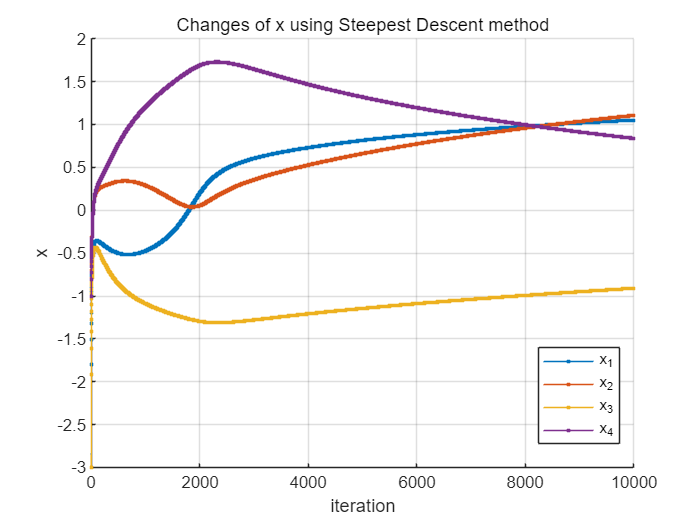

xHistorySteepest = x0Wood;
xValuesSteepest = fcnWood(x0Wood);
% Initializing
x_prev = x0Wood;
max_iter = 10000;
iter = 1;
is_converged = false;
k = 0.0001;
while iter < max_iter
    x_new = x_prev - k*gradWood(x_prev);
    xHistorySteepest = [xHistorySteepest, x_new];
    xValuesSteepest = [xValuesSteepest, fcnWood(x_new)];
    if (fcnWood(x_prev) < fcnWood(x_new))
        break;
    end
    x_prev = x_new;
    iter = iter + 1;
end

figure;
hold on; grid on;
steepestX1 = plot(1:1:max_iter, xHistorySteepest(1,:), '.-');
steepestX2 = plot(1:1:max_iter, xHistorySteepest(2,:), '.-');
steepestX3 = plot(1:1:max_iter, xHistorySteepest(3,:), '.-');
steepestX4 = plot(1:1:max_iter, xHistorySteepest(4,:), '.-');
legend([steepestX1, steepestX2, steepestX3, steepestX4], {"x_1", "x_2", "x_3", "x_4"}, "Location", "best");
xlabel("iteration"); ylabel("x"); title("Changes of x using Steepest Descent method");

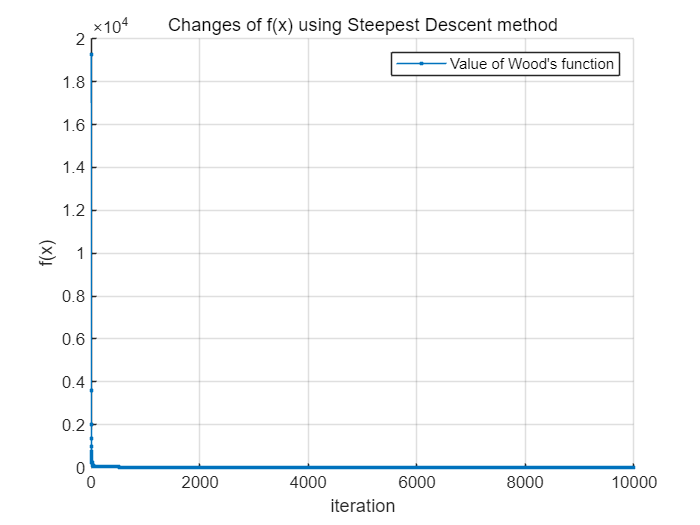

figure;
[steepestVal, steepestIdx] = min(xValuesSteepest);
hold on; grid on;
steepestValues = plot(1:1:max_iter, xValuesSteepest, '.-');
legend(steepestValues, {"Value of Wood's function"});
xlabel("iteration"); ylabel("f(x)"); title("Changes of f(x) using Steepest Descent method");

With 10000 iteration and $k=0\ldotp 0001$, the output of Wood's function with steepest descent method was converging and its value was $3\ldotp 7087$ at 10000 iteration.

Using **Conjugate Gradient method.**

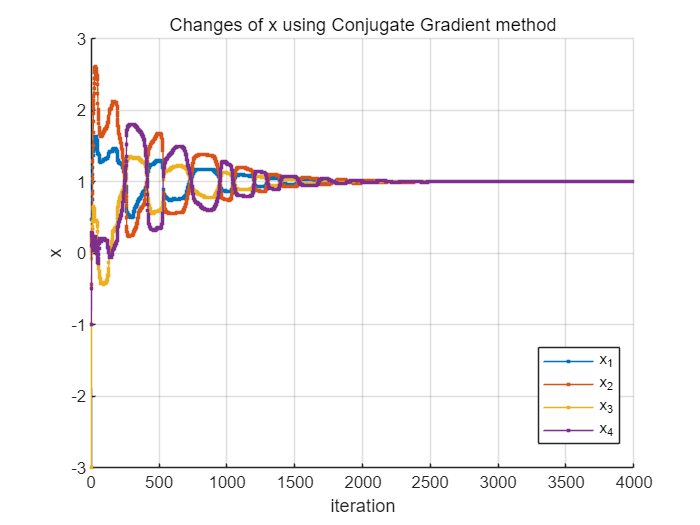

xHistoryConjugate = x0Wood;
xValuesConjugate = fcnWood(x0Wood);
% Initializing
max_iter = 10000;
iter = 1;
is_converged = false;
is_first = true;
threshold = 1e-12;
margin = [0, 1]; % Bi-section searching margin
x_prev = x0Wood;
% Numerical optimization loop
while and(iter < max_iter, ~is_converged)
    x_grad = gradWood(x_prev);
    if is_first
        is_first = false;
        dir_prev = -x_grad;
        alpha = bi_section_search(fcnWood, x_prev, dir_prev, margin);
    else
        beta = (x_grad'*x_grad)/(x_grad_prev'*x_grad_prev);
        dir = -x_grad + beta * dir_prev;
        alpha = bi_section_search(fcnWood, x_prev, dir, margin);
        dir_prev = dir;
    end
    x_new = x_prev + alpha*dir_prev;
    if abs(fcnWood(x_new) - fcnWood(x_prev)) < threshold
        is_converged = true;
    end
    % if fcnWood(x_prev) < fcnWood(x_new)
    % break;
    % end

    x_prev = x_new;
    x_grad_prev = x_grad;
    xHistoryConjugate = [xHistoryConjugate, x_prev];
    xValuesConjugate = [xValuesConjugate, fcnWood(x_prev)];
    iter = iter + 1;
end

figure;
hold on; grid on;
conjugateX1 = plot(1:1:length(xHistoryConjugate), xHistoryConjugate(1,:), '.-');
conjugateX2 = plot(1:1:length(xHistoryConjugate), xHistoryConjugate(2,:), '.-');
conjugateX3 = plot(1:1:length(xHistoryConjugate), xHistoryConjugate(3,:), '.-');
conjugateX4 = plot(1:1:length(xHistoryConjugate), xHistoryConjugate(4,:), '.-');
legend([conjugateX1, conjugateX2, conjugateX3, conjugateX4], {"x_1", "x_2", "x_3", "x_4"}, "Location", "best");
xlabel("iteration"); ylabel("x"); title("Changes of x using Conjugate Gradient method");

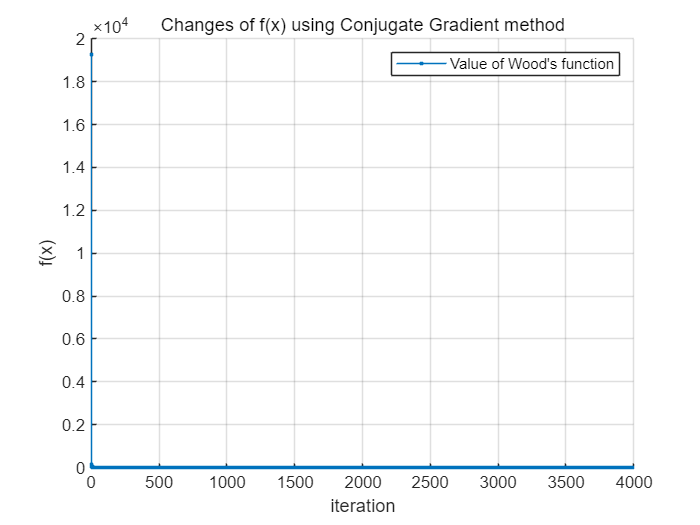

figure;
[conjugateVal, conjugateIdx] = min(xHistoryConjugate);
hold on; grid on;
steepestValues = plot(1:1:length(xHistoryConjugate), xValuesConjugate, '.-');
legend(steepestValues, {"Value of Wood's function"});
xlabel("iteration"); ylabel("f(x)"); title("Changes of f(x) using Conjugate Gradient method");

With 3992 iteration, the output of Wood's function with **conjugate gradient method **was converging and its value was $2\ldotp 6077e-09$ at 3992 iteration.

The conjugate gradient method shows fewer iteration and lower output of function than steepest descent method.

%% Function of Bi section search method
function alpha = bi_section_search(fcn, x_k, d_k, margin)
    if any(margin < 0)
        error("Margin should not be negative");
    end
    
    upperBound = max(margin);
    lowerBound = min(margin);
    thres = 1e-5;
    while abs(upperBound - lowerBound) > thres
        mid = (upperBound + lowerBound)/2;
        f_lower = fcn(x_k + lowerBound*d_k);
        f_mid = fcn(x_k + mid*d_k);
        f_upper = fcn(x_k + upperBound*d_k);
        if and(f_mid < f_lower, f_mid < f_upper)
            diff_low = abs(f_mid - f_lower);
            diff_upp = abs(f_upper - f_mid);
            if diff_low < diff_upp
                upperBound = mid;
            else
                lowerBound = mid;
            end
            alpha = mid;
        else
            if f_lower < f_upper
                upperBound = mid;
            else
                lowerBound = mid;
            end
            alpha = (lowerBound + upperBound)/2;
        end
    end
end